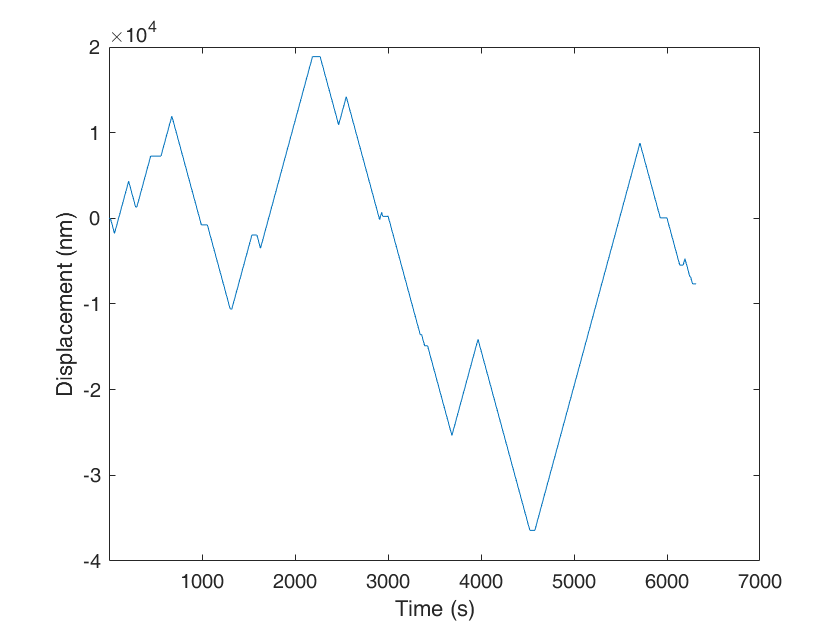

motorPar.eps0=0.2/60;%single motor unbinding rate s^-1
motorPar.pi0 =0.4/60; %single motor binding rate s^-1
motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.Nplus=1;%total number of plus motors 
motorPar.Nminus=1;%total number of bound plus motors 
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s

motorState=motorPar;
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

%motorDynamics = lipowskiModel(motorState)

[dynamics] = lipowskiSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

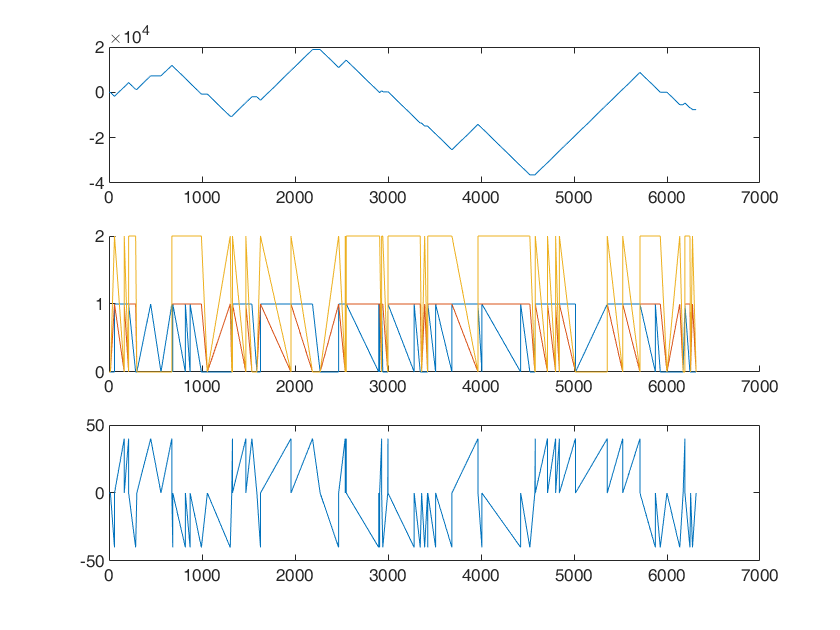


subplot(3,1,1);
plot(t,x);
subplot(3,1,2);
hold all;
plot(t,nPlus);
plot(t,nMinus);
plot(t,nMinus+nMinus);
subplot(3,1,3);
plot(t,vCargo);

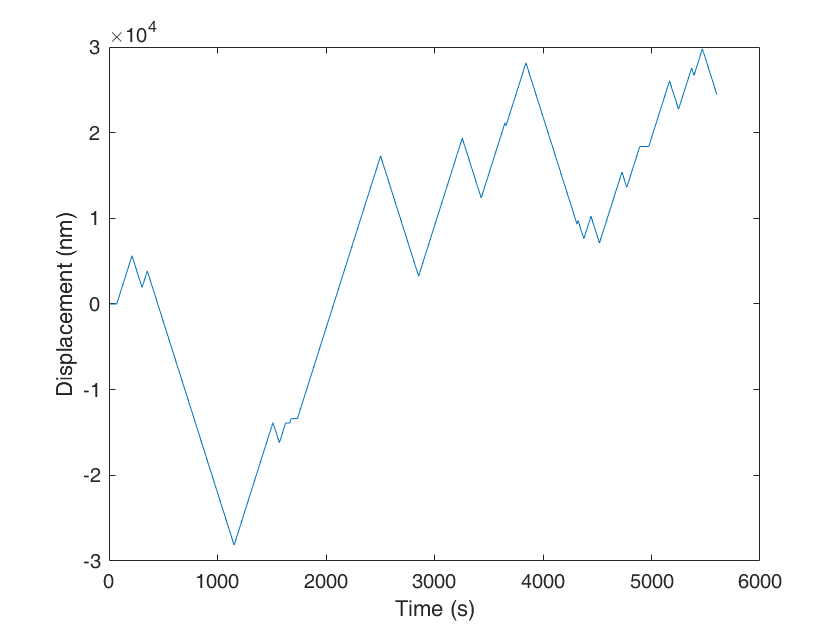

%lipowski sim with unbinding

%UNIT Tests to check model behaves as expected
%Nmotors = 1 each side, high concentration, low unbinding,  which should recapitulate the stable tug of war
%model
motorPar.eps0=0.01/60;%single motor unbinding rate s^-1
motorPar.pi0 =0.4/60; %single motor binding rate s^-1
motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration = 1000;%arb units, essentiall scaling of low synthase concentration data here
motorPar.kOn0 = 0.02/60; %rate of single motor (synthase) binding to cargo (mreB) (Guess - waiting for stu data)
motorPar.kOff0 = 0; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

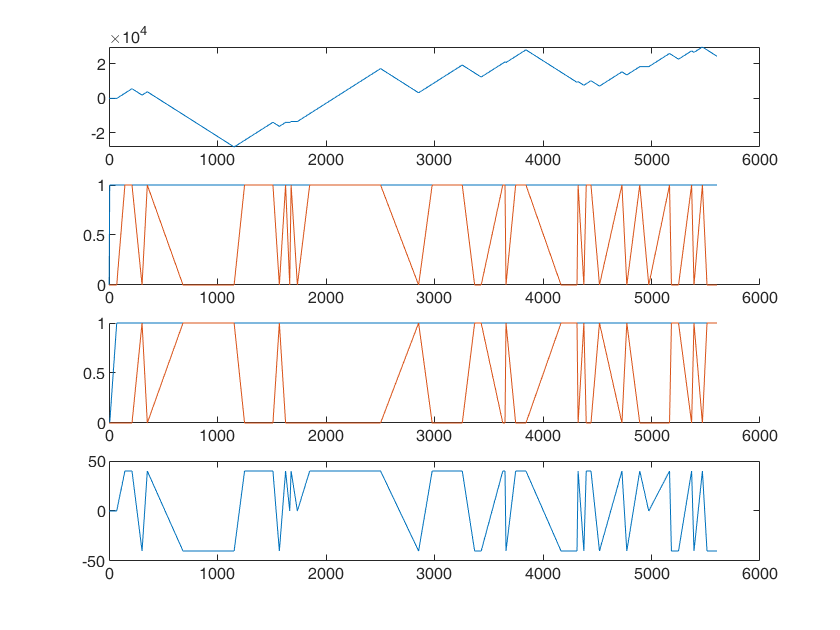

subplot(4,1,1);
plot(t,x);
subplot(4,1,2);
hold all;
plot(t,Nplus);
plot(t,nPlus);
subplot(4,1,3);
hold all
plot(t,Nminus);
plot(t,nMinus);
subplot(4,1,4);
plot(t,vCargo);

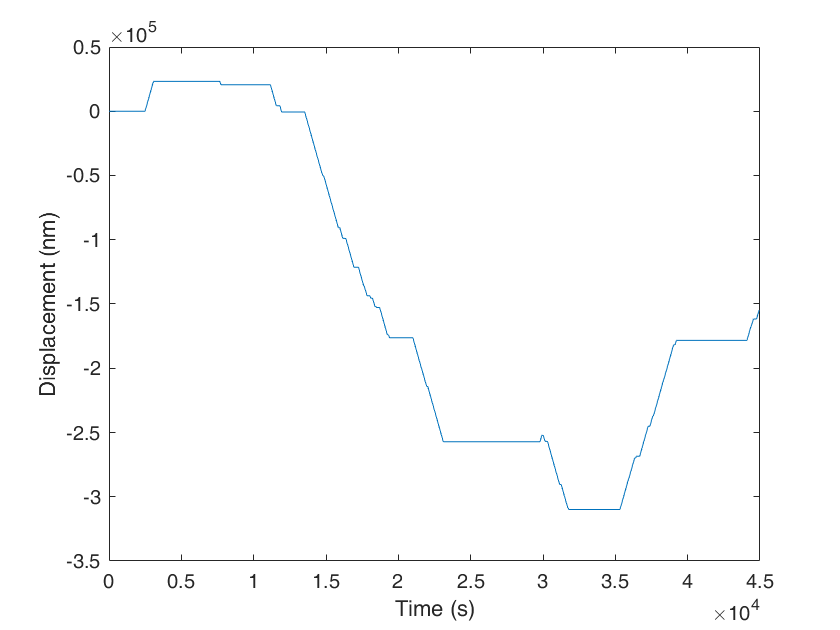

%UNIT Tests to check model behaves as expected
%Nmotors = 1 each side, low concentration, low unbinding,  which should recapitulate
%pausing
%model
motorPar.eps0=0.2/60;%single motor unbinding rate s^-1
motorPar.pi0 =0.4/60; %single motor binding rate s^-1
motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration = 0.01;%arb units, essentiall scaling of low synthase concentration data here
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.kOff0 = 0.2/60; %rate of single motor (synthase) unbinding from cargo (mreB)
motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

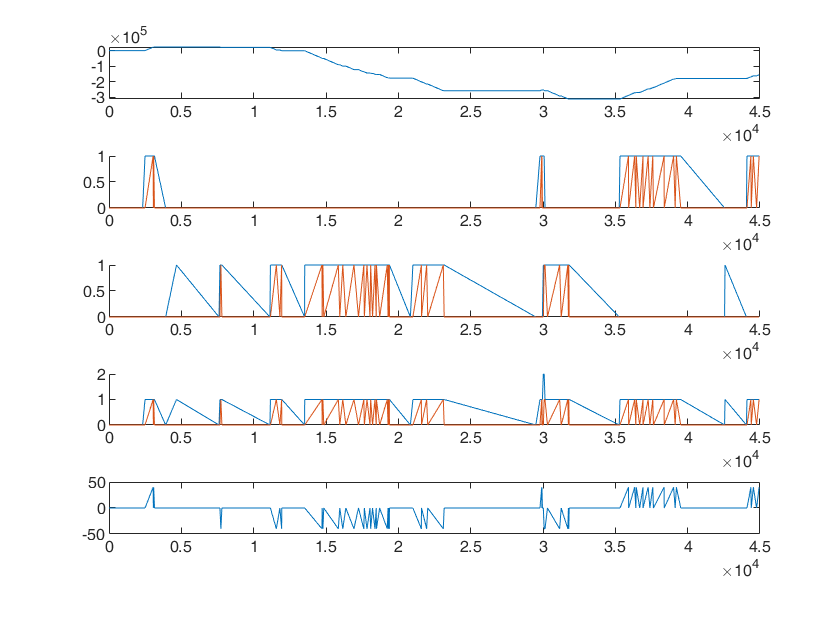

subplot(5,1,1);
plot(t,x);
subplot(5,1,2);
hold all;
plot(t,Nplus);
plot(t,nPlus);
subplot(5,1,3);
hold all
plot(t,Nminus);
plot(t,nMinus);
subplot(5,1,4);
hold all
plot(t,Nminus+Nplus);
plot(t,nMinus+nPlus);
subplot(5,1,5);
plot(t,vCargo);

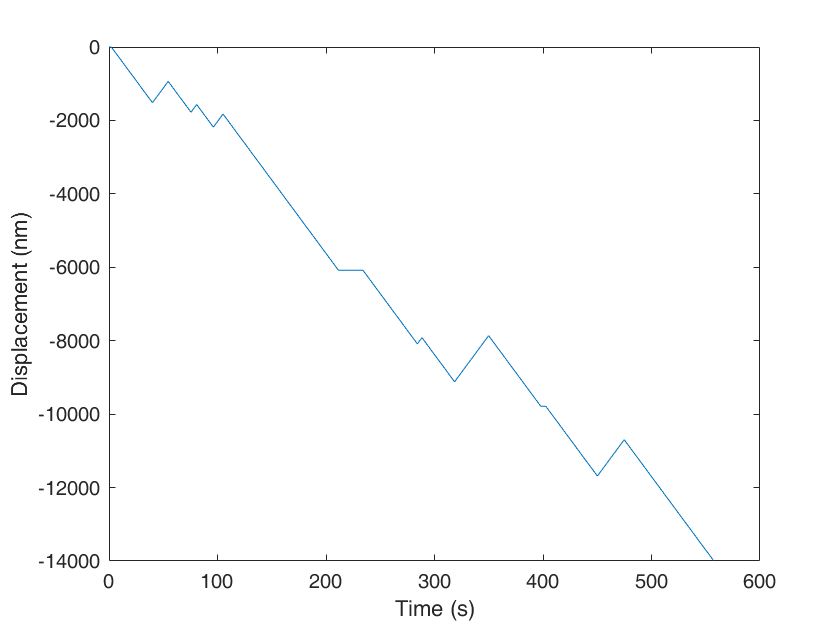

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration
%processivity is synthesis limited
motorPar.kOff0 = 10*motorPar.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)

motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration =10;%arb units, essentiall scaling of low synthase concentration data here

motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

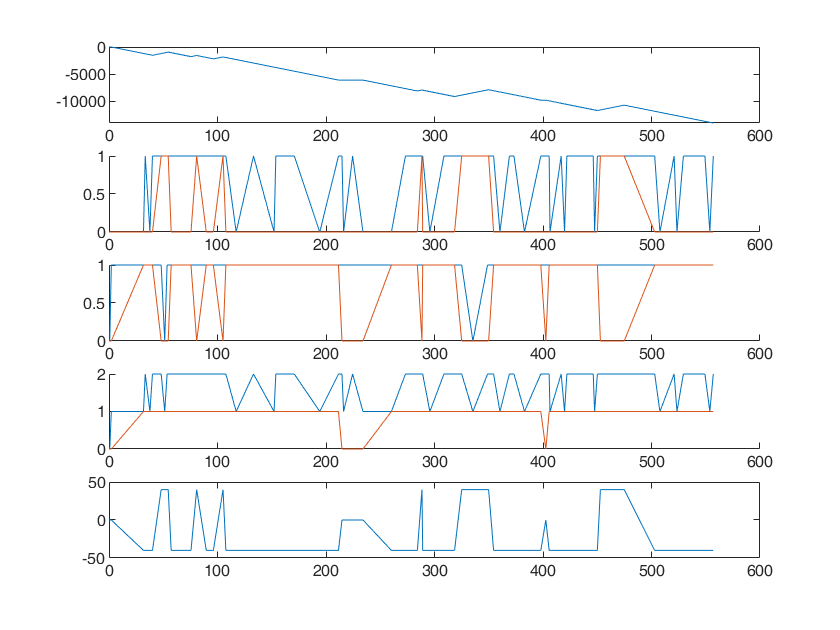

subplot(5,1,1);
plot(t,x);
subplot(5,1,2);
hold all;
plot(t,Nplus);
plot(t,nPlus);
subplot(5,1,3);
hold all
plot(t,Nminus);
plot(t,nMinus);
subplot(5,1,4);
hold all
plot(t,Nminus+Nplus);
plot(t,nMinus+nPlus);
subplot(5,1,5);
plot(t,vCargo);motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)

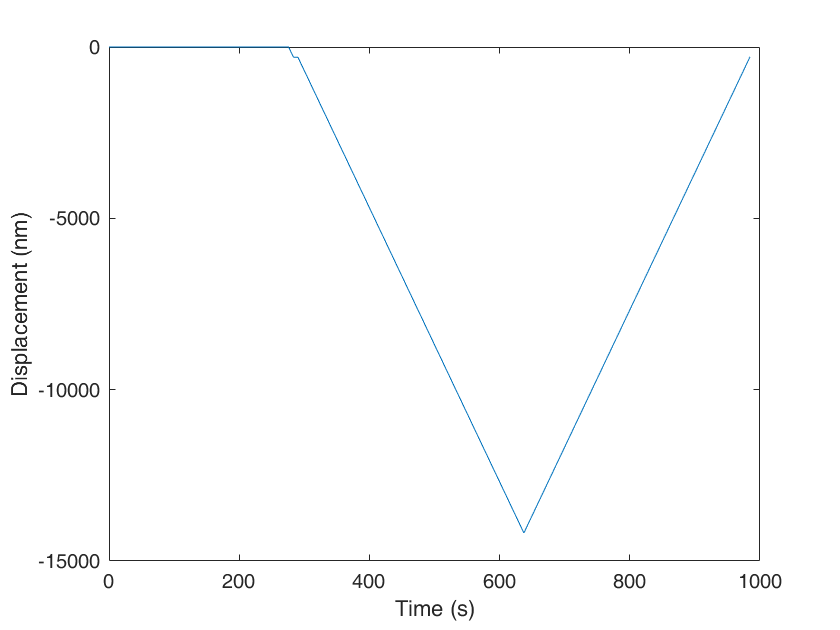

%ALLOW MORE THAN ONE MOTOR PER END
% motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration
%processivity is synthesis limited
motorPar.kOff0 = 10*motorPar.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)

motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = inf;
motorPar.motorConcentration =1;%arb units, essentiall scaling of low synthase concentration data here

motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;

figure;
plot(t,x);
ylabel('Displacement (nm)');
xlabel('Time (s)');

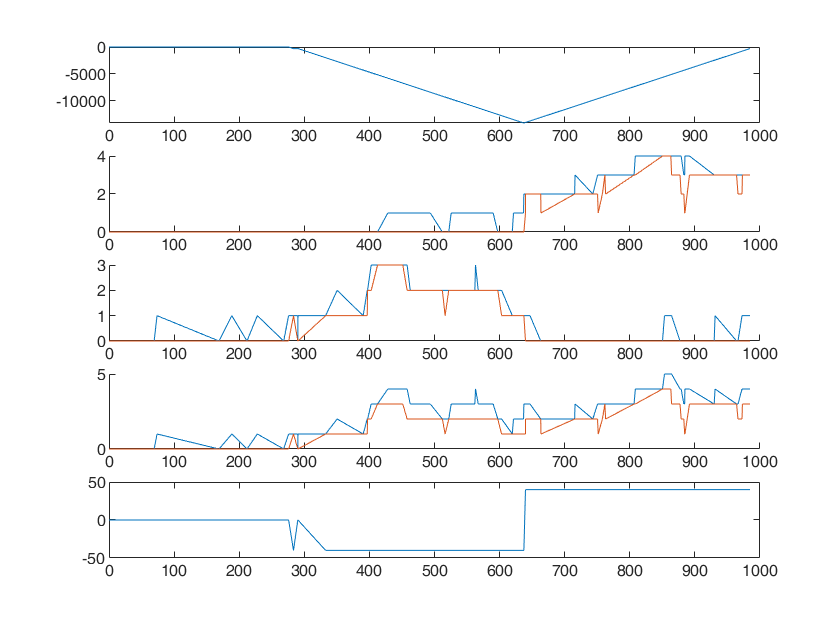

subplot(5,1,1);
plot(t,x);
subplot(5,1,2);
hold all;
plot(t,Nplus);
plot(t,nPlus);
subplot(5,1,3);
hold all
plot(t,Nminus);
plot(t,nMinus);
subplot(5,1,4);
hold all
plot(t,Nminus+Nplus);
plot(t,nMinus+nPlus);
subplot(5,1,5);
plot(t,vCargo);

TODO:

Think of a decent unit test to check the model is giving expected rates (binding/ unbinding?)

Implement automatic estimation of processivity, pausing and reversal rate (of processive complexes). Make some param to ignore short events

Measure change in reversal/ pausing rate vs max # of motors